# FitzHugh-Nagumo model

by Gabrielle Gutierrez, PhD for CAMP 2023


$$\dot{V} = V(a-V)(V-1)-W + I_{stim} \\
\dot{W} = bV-cW$$


% parameters
I_stim = 0; % stimulus current
a = 0.1; 
b = 0.01; 
c = 0.02;

The initial conditions for V and W.

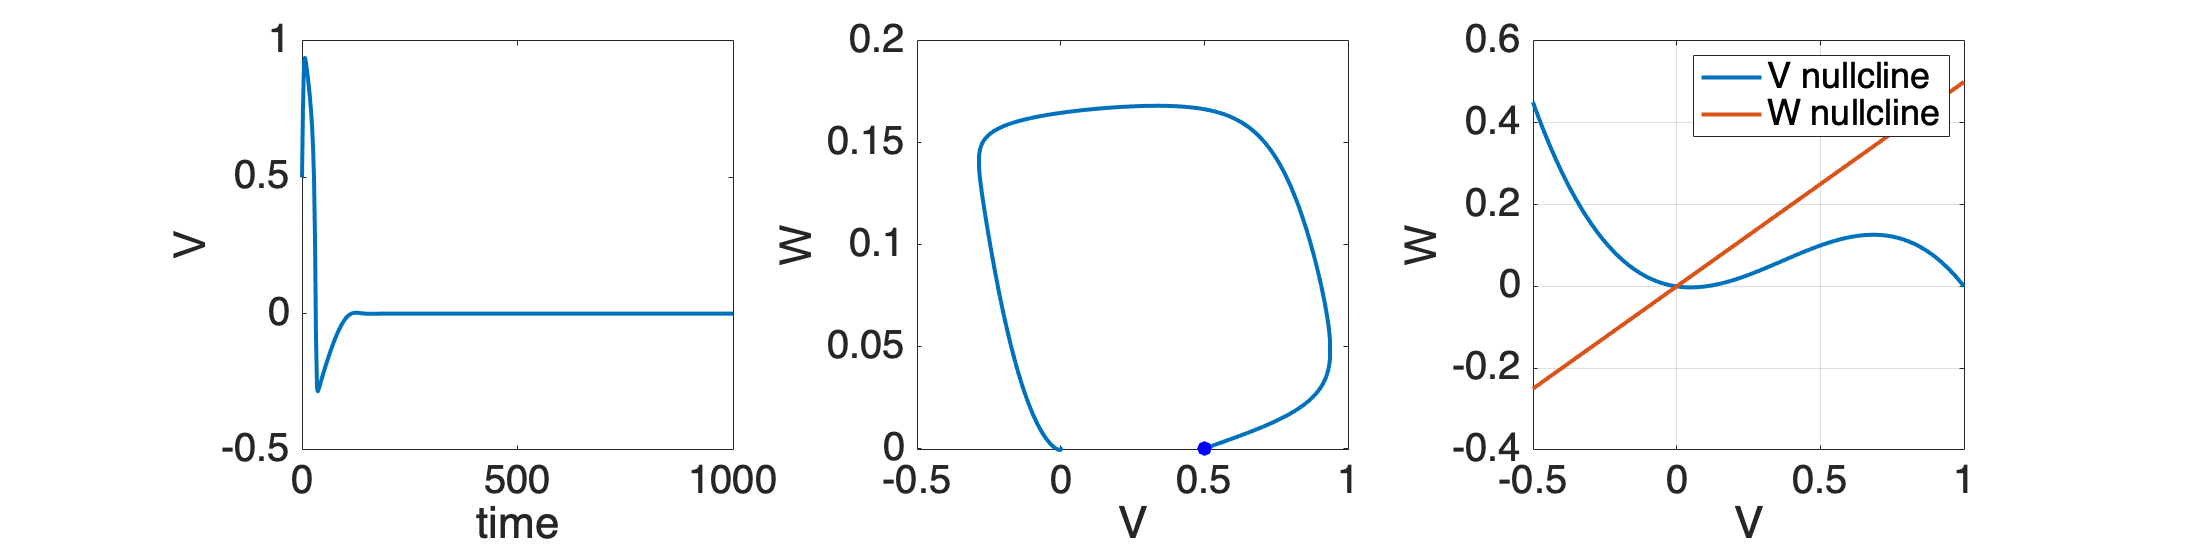

V_init = 0.5;
W_init = 0;

% time base
dt = 0.01;
tmax = 1000; %seconds
time = 0:dt:tmax;

% allocate vectors for the dynamical variables
V = zeros(size(time)); % membrane potential
W = zeros(size(time)); % recovery variable

% initial conditions
V(1) = V_init;
W(1) = W_init;

% compute variables over time
for t = 1:length(time)-1

    % Izhikevich formulation
    dV = (V(t)*(a-V(t))*(V(t)-1) - W(t) + I_stim)*dt;
    V(t+1) = V(t) + dV;

    dW = (b*V(t) - c*W(t))*dt;
    W(t+1) = W(t) + dW;

end

% nullclines
Vrange = -1:0.01:1;
V_null = Vrange.*(a-Vrange).*(Vrange-1)+I_stim;
W_null = Vrange.*b/c;

fig = figure(); 
fig.Position(3:4) = [2000, 500];
fon = 20;

subplot(1,3,1)
plot(time, V,'LineWidth',2)
xlabel('time')
ylabel('V')
set(gca,'FontSize',fon)

subplot(1,3,2)
plot(V,W,'LineWidth',2)
hold on 
plot(V(1),W(1),'b.','MarkerSize',25)
xlabel('V')
ylabel('W')
set(gca,'FontSize',fon)

subplot(1,3,3)
plot(Vrange,V_null,'LineWidth',2)
hold on
plot(Vrange,W_null,'LineWidth',2)
grid on
set(gca,'FontSize',fon)
xlim([-0.5 1])
xlabel('V')
ylabel('W')
legend('V nullcline','W nullcline')

V-nullcline: $W=V(a-V)(V -1)+I_{stim}$

W-nullcline: $W = \frac{b}{c}V$

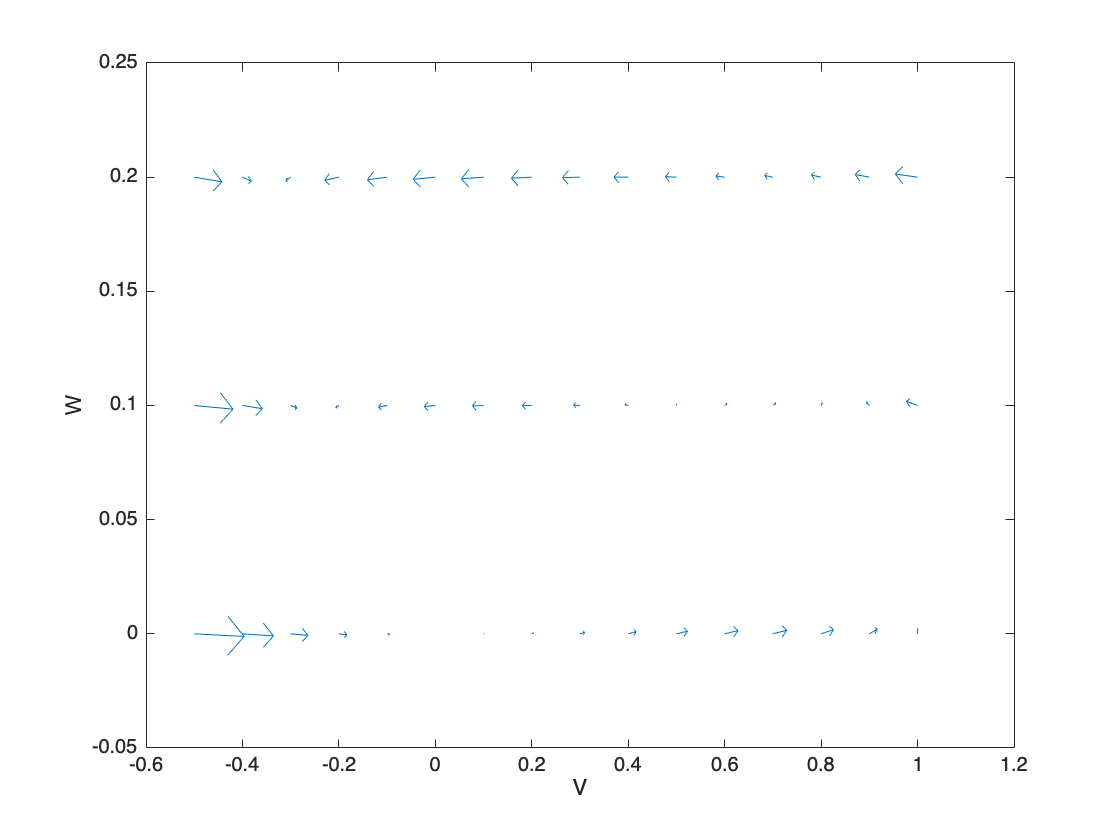

% flow field
[x,y] = meshgrid(-0.5:0.1:1,0:0.1:0.2);

dx = (x.*(a-x).*(x-1) - y + I_stim);
dy = (b.*x - c.*y);

figure
quiver(x,y,dx,dy)
xlabel('V')
ylabel('W')